# Válogatott modellek a matematikai biológiában

# 2. gyakorlat

### Diffúzió egyenlet megoldása Dirichlet, Neumann és periodikus peremfeltételek mellett

Időbeli ($\tau$) ill. térbeli $(h)$ lépésközök megválasztása:

dt = 0.1;
dx = 1;

Időhorizont amelyen vizsgálom a dinamikát (mintavételi pontok száma): 

nt = 1500;

Kémcső / rúd / ált. közeg hossza:

L = 200;

Diffúzió sebessége:

D = 2;

A diszkretizációt követően az egyenletben szereplő $\mu = D \frac{\tau}{h^2}$ értéke:

mu = D*dt/dx^2;

Emlékezzünk, a diszkretizáció eredménye:


$$u_{i+1,j} = u_{i,j-1} + (1-2\mu) u_{i,j} + u_{i,j+1}$$


Vizsgált pontok a térdimenzió mentén, illetve a vizsgált pontok száma:

x = 1:dx:L;
nx = length(x);

A teljes $u(t,x)$ függvény numerikus közelítésének mátrix alakja, $U = \big(u_{i,j}\big)_{i=1,\dots,n_t,\,j=1,\dots,n_x}$

U = zeros(nx,nt);

Lehetséges kezdeti feltételek

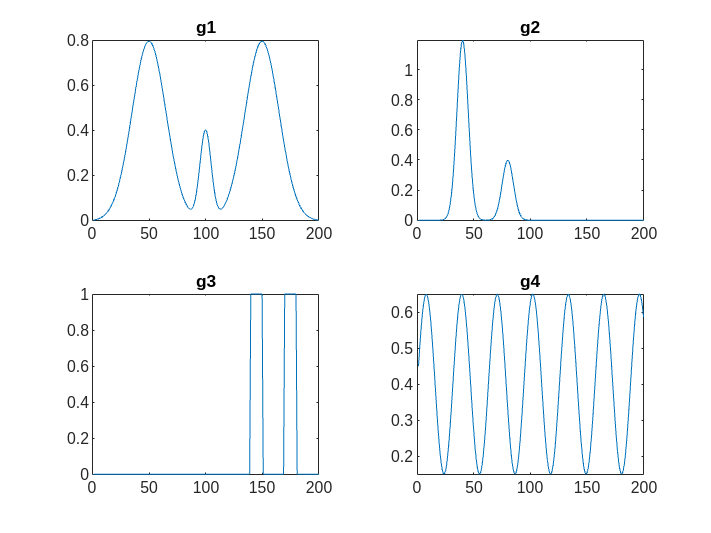

g1 = normpdf(x,L/4,15)*30 + normpdf(x,L/2,5)*5 + normpdf(x,3*L/4,15)*30;
g1 = g1 - min(g1);

g2 = normpdf(x,1*L/5,5)*15 + normpdf(x,2*L/5,5)*5;
g2 = g2 - min(g2);

g3 = zeros(nx,1);
g3(170:180) = 1;
g3(140:150) = 1;

g4 = 0.4+sin(1/5*x)/4;

fig = figure(1);
delete(fig.Children)
nexttile; plot(x,g1); title g1
nexttile; plot(x,g2); title g2
nexttile; plot(x,g3); title g3
nexttile; plot(x,g4); title g4


fig = figure;
fig.Visible = 'on';

u = g2;
u_ip1 = u;
for i = 1:nt % minden időpillanatban
    for j = 1:nx % minden pontban kiszámolom a hullám aktuális értékét   
        % minden pontra kiszámoljuk az új értékét explicit Euler módszerrel:              
        if j == 1 % peremek
            % 1. fix perem (Dirichlet perem): alapból is ez van, torzít a széleken, lefolyik az anyag, 0 lesz
            % u_ip1(j) = 0; 
 
            % 2. Neumann perem: gradiens 0 széleken=utolsó és utolsó elötti pozíció mindig ugyanazon az értéken van, kiegyenlítõdik az átlaghoz
            u_ip1(j) = (1-mu)*u(j) + mu*u(j+1);  

            % 3. periodikus határ: az elsõ és az utolsó pozíció összekapcsolva, kör lesz, kiegyenlítõdik az átlaghoz 
            % u_ip1(j) = mu*u(end) + (1-2*mu)*u(j) + mu*u(j+1); 
        elseif 1 < j && j < nx
            u_ip1(j) = mu*u(j-1) + (1-2*mu)*u(j) + mu*u(j+1); %dU/dt=D*dU^2/dx^2 %diffúzió, szétfolyik
        else % peremek
            % 1. fix perem (Dirichlet perem): alapból is ez volt, torzít a széleken felolyik az anyag
            % u_ip1(j) = 0; 
            
            % 2. Neumann perem: gradiens 0 széleken=utolsó és utolsó elötti mindig ugyanazon az értéken van, kiegyenlítõdik az átlaghoz
            u_ip1(j) = mu*u(j-1) + (1-mu)*u(j);
            
            % 3. periodikus határ: az elsõ és az utolsó pozíció összekapcsolva, kör lesz, kiegyenlítõdik az átlaghoz
            % u_ip1(j) = mu*u(j-1) + (1-2*mu)*u(j) + mu*u(1); 
            
        end
    end
    u = u_ip1;
    
    %if mod(t,100)==0 %hosszú futásnál minden 100.-at rajzol csak ki
    plot(x,u); % aktuális értékeket kirajzol
    grid(gca, 'minor'); % sûrû rácsot tesz a képre
    ylim([-0.5 1.5]); %ábrázolás határai
    xlim([1, 200]);%xlim([10, 190]);%
    title(['lépés: ', num2str(i)]); %kiírítja az ábrára, hogy hányadik lépésnél vagyok
    drawnow
    %end
     
    U(:,i) = u;
end

mesh(U); %ha az idõbeli változásokat 1 ábrán akarjuk nézni

%halad a csúcs ha u(i+1)=u2(i) + mu*(u2(i+1)-2*u2(i)+u2(i-1));
% a rendszer elszáll, ha:
%D*2*dt/dx^2>1